Headers

addpath('MATLAB-Tempogram-Toolbox');
addpath('QXI');
addpath('Benetos');
dirWav = 'audio_wav/';
filename = 'AHa_TakeOnMe_STEM_04_test.wav';
% filename = 'AlexanderRoss_GoodbyeBolero_STEM_01_excerpt.wav';

Loading Audio

param_load_audio.vis=0;
[audio,sideinfo] = wav_to_audio('',dirWav,filename,param_load_audio);
fs = sideinfo.wav.fs;

Run Novelty

parameter_novelty = [];
[novelty_curve,feature_fs] = audio_to_noveltyCurve(audio, fs, parameter_novelty);

Visualize Novelty

novelty_timevec = (0:length(novelty_curve)-1)./feature_fs; % time in sec

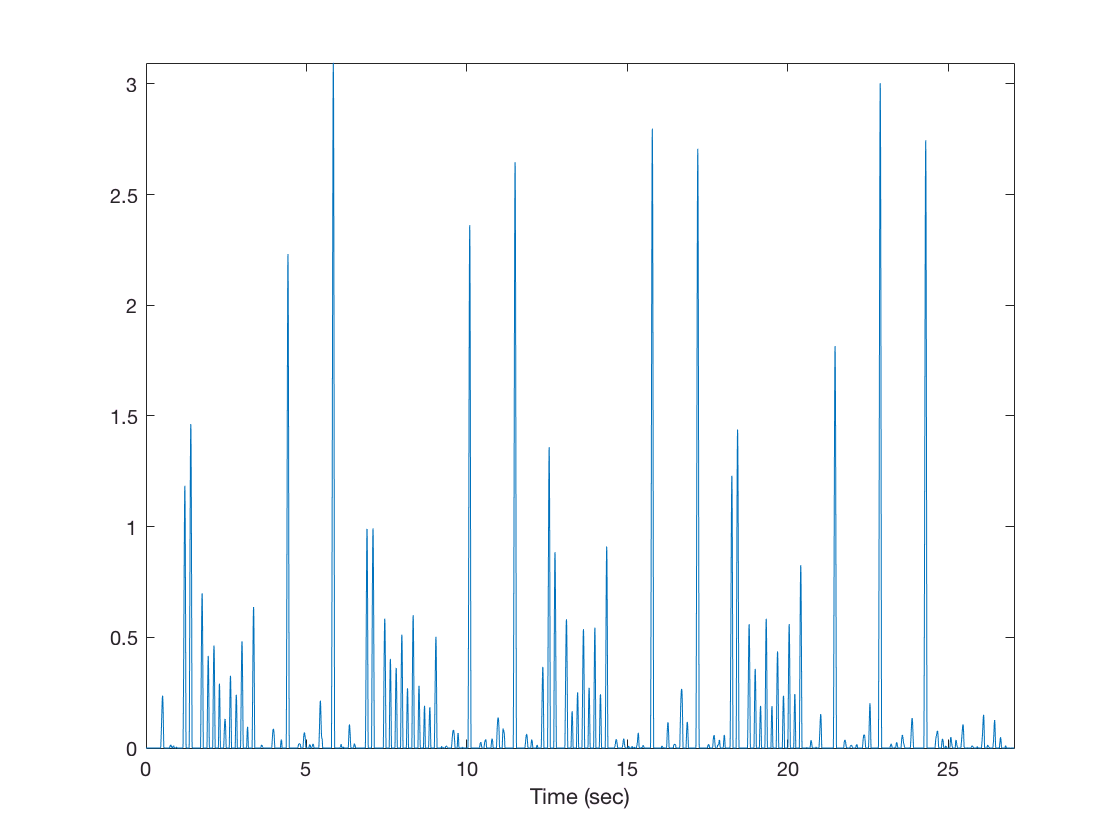

plot(novelty_timevec,novelty_curve);
axis tight;
xlabel('Time (sec)');

Pick onset from novelty curve:

w_c = 6; medfilt_len = 9; offset = 0.004;
[onset_amp, onset_time, novelty_smoothed, thresh] = ...
    onsets_from_novelty(novelty_curve, novelty_timevec, feature_fs, w_c, medfilt_len, offset);

% plot(novelty_timevec,novelty_curve, 'r-');
% hold on
% plot(novelty_timevec,novelty_smoothed, 'k-');
% plot(novelty_timevec,thresh, 'b:');
% plot(onset_t, onset_a, 'ko');
% xlim([0 10.0])
% ylim([-0.1 1])
% hold off

sonify_param.outpath = 'audio_wav/mySonify.wav';
sonify_param.audio_fs = fs;
sonify_param.feature_fs = feature_fs;
sonify_onset(onset_time,onset_amp,audio,sonify_param);

Using onset_time to chunk chunk transcription

filepath = strcat(dirWav,filename);
raw_piano_roll = transcription(filepath,50,3,1.0,1.0,1.0);

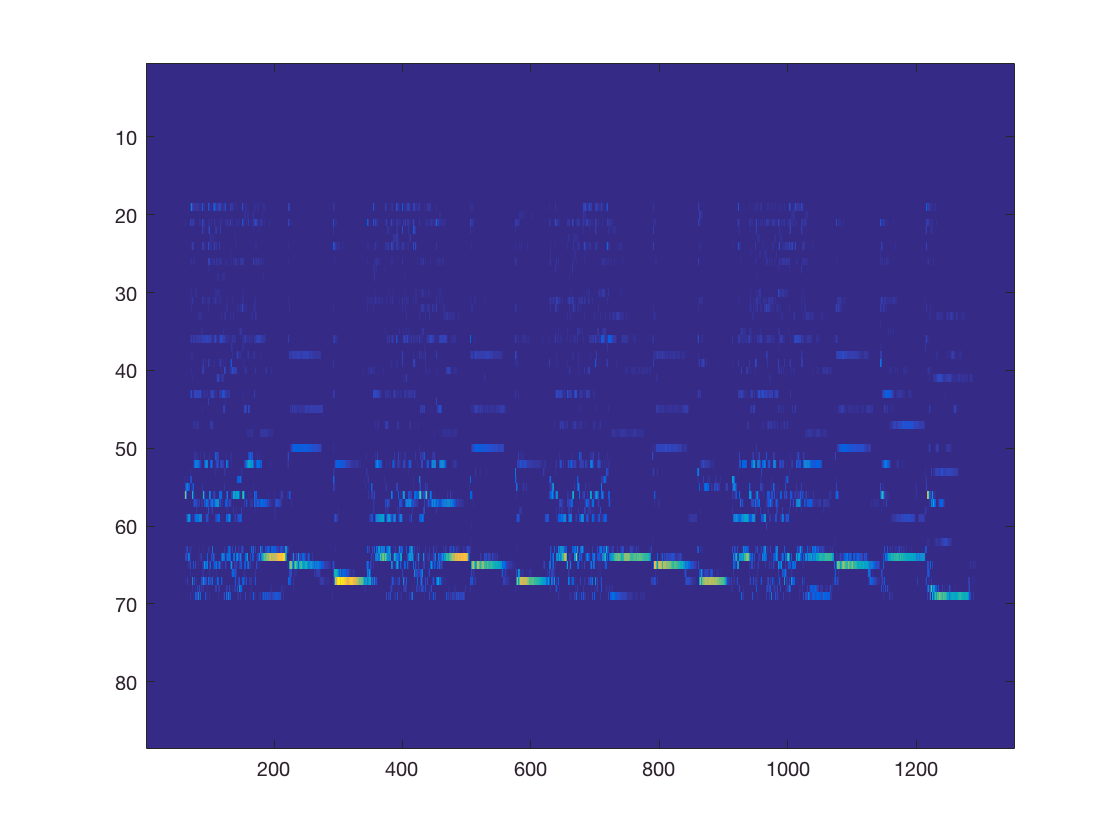

imagesc(flipud(raw_piano_roll));

roll_fs = size(raw_piano_roll,2) / sideinfo.wav.duration;
[chunked_roll, full_roll] = chunk_n_average(raw_piano_roll, roll_fs, onset_time);

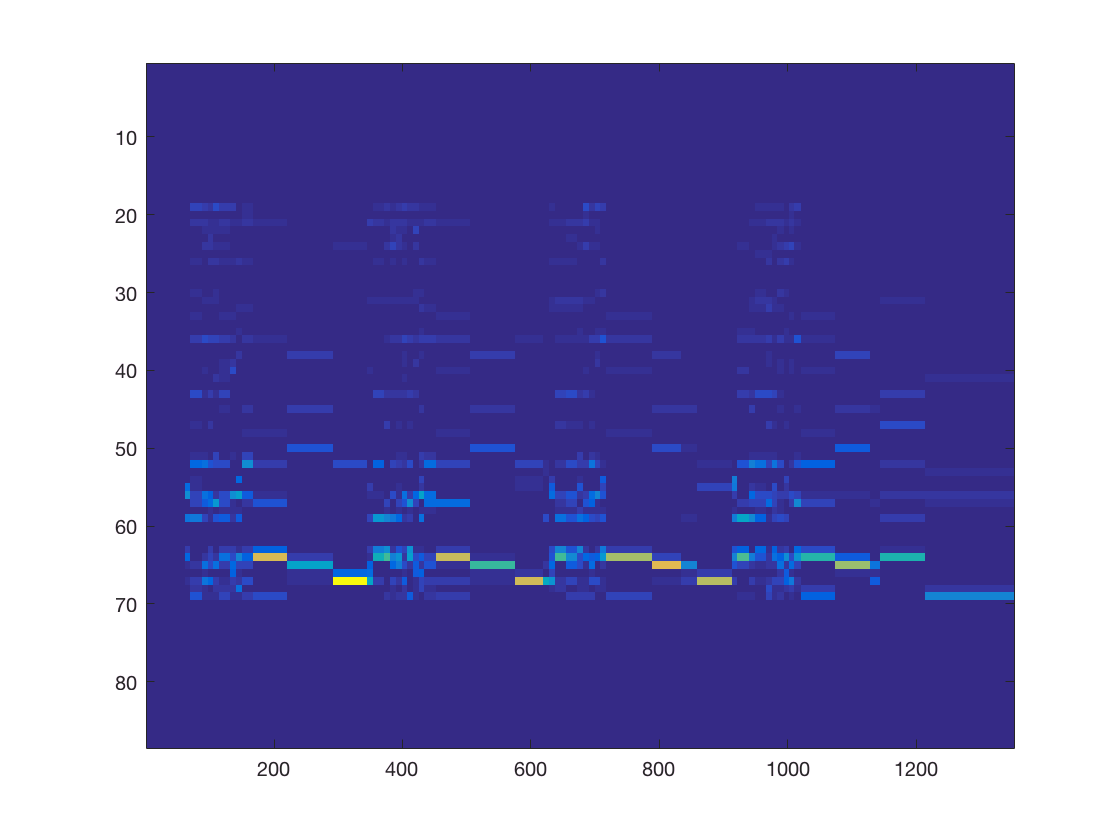

imagesc(flipud(full_roll));

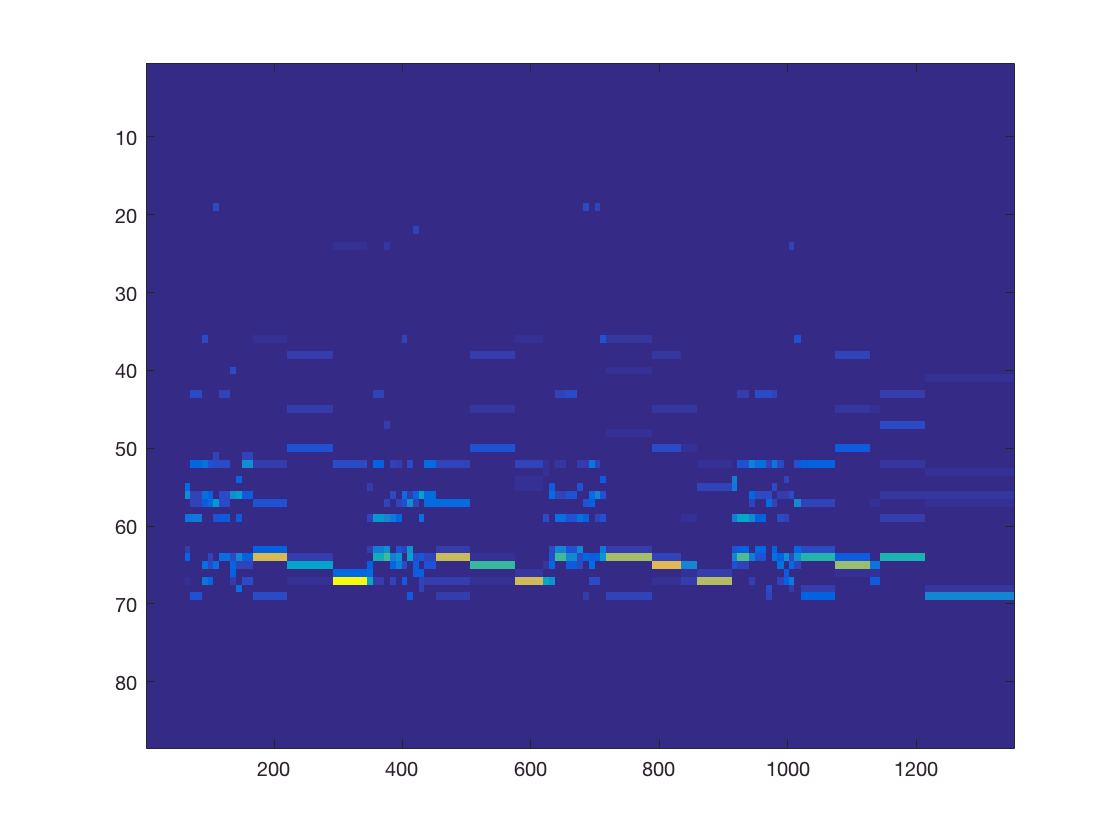

candidate_roll = max_n_per_col(full_roll, 6);
imagesc(flipud(candidate_roll));

save('./python/onset_time.mat', 'onset_time'); 
save('./python/chunked_roll.mat', 'chunked_roll');